# Assignment 3 (BPSK and QPSK)

AbdulRahman Ateyya AbdulNabi - 202001398

Generate test signal

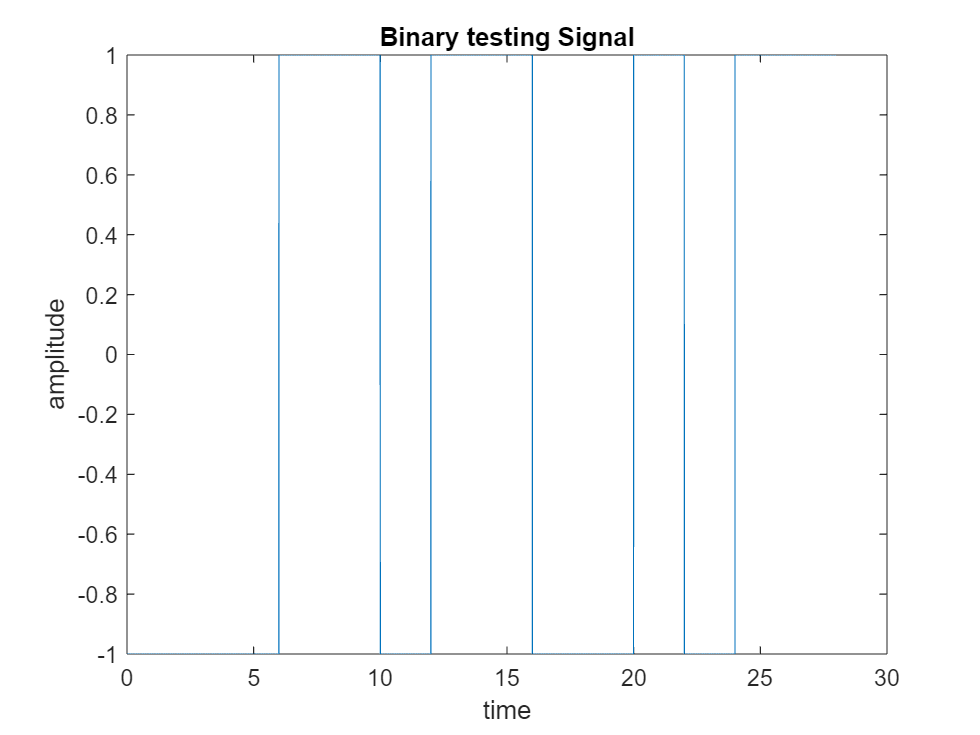

% Testing Signal
% b= [1 0 1 0 0 1 1 0 0 1 0 1 0 1 1 1 0 0 0 1 0 1 0 1 0 1 0 1 0];
b= [0 0 0 1 1 0 1 1 0 0 1 0 1 1];
L=length(b);
Tb=2;
dt=0.001;
tt= 0:dt:L*Tb;
tb = 0:dt:Tb;
tb(end)=[];

sig_test=polarNRZ(b,Tb,dt,L); %local function, at the end of the file..

figure(1)
plot(tt,sig_test)
title('Binary testing Signal')
xlabel('time')
ylabel('amplitude')

BPSK 

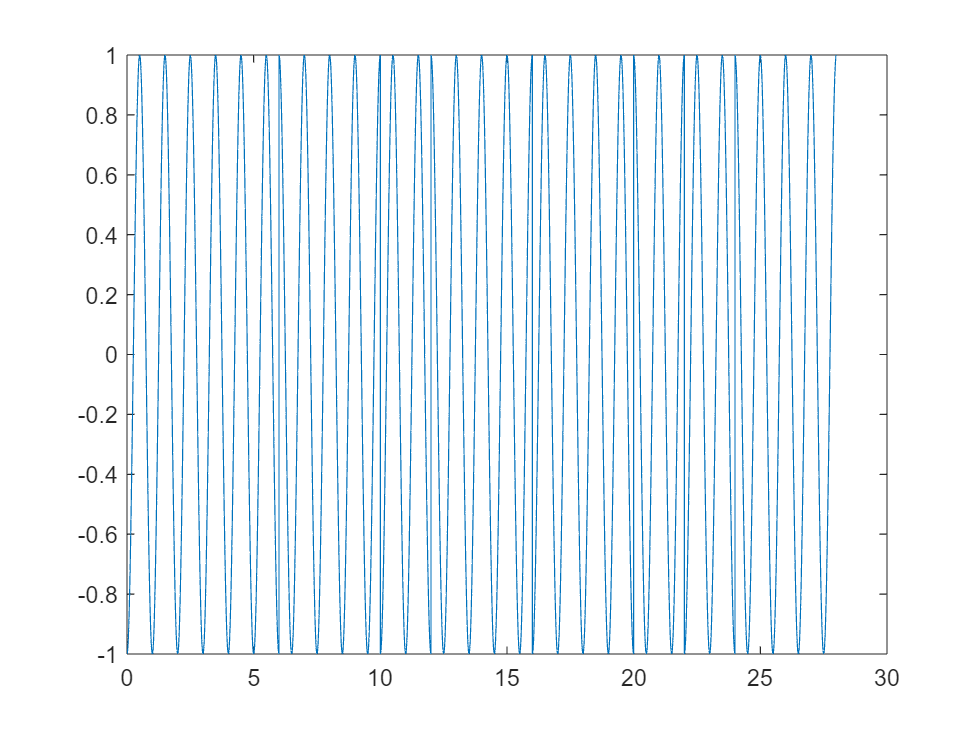

% Modulation
M=2;
f1=1;
f2=10;
[modulated,y_i,y_q,~]= PSK_mod(b,Tb,dt,M);

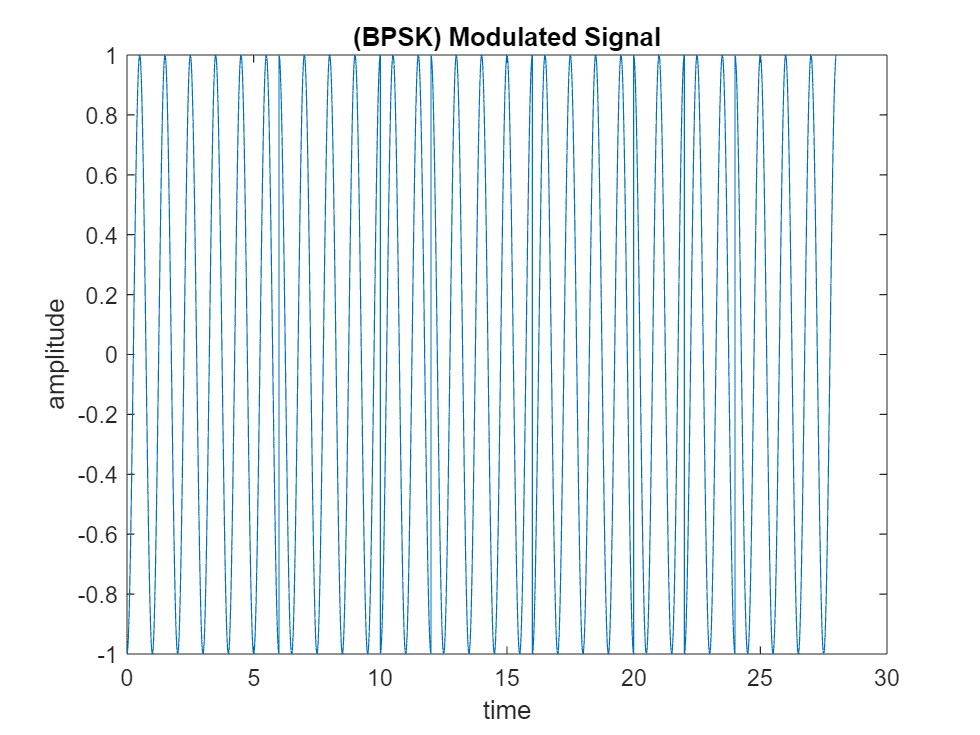

figure(2)
plot(tt,modulated);
title('(BPSK) Modulated Signal')
xlabel('time')
ylabel('amplitude')

% figure(3)
%     subplot(3,1,1)
%     plot(tt,y_i)
%     subplot(3,1,2)
%     plot(tt,y_q)
%     subplot(3,1,3)
%     plot(tt,y_PSK);

Adding Noise to Signal

snr=5;
noisy_signal= awgn(modulated,snr);
figure(3)
plot(tt,noisy_signal)
title('BPSK Noisy Transmitted Signal')
xlabel('time')
ylabel('amplitude')

Demodulation

A=sqrt(2/Tb);
f=1;
demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M)

demodulated =      0     0     0     1     1     0     1     1     0     0     1     0     1     1


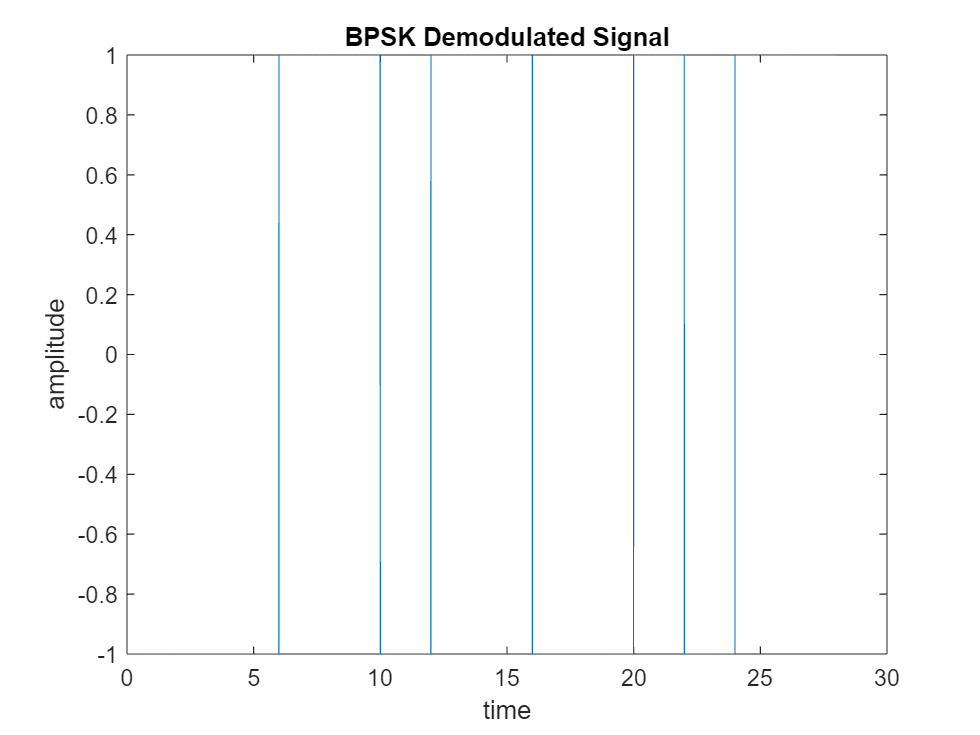

sig_demod= polarNRZ(demodulated,Tb,dt,L);
figure(4)
plot(tt,sig_demod)
title('BPSK Demodulated Signal')
xlabel('time')
ylabel('amplitude')

Add all to one plot for comarison

figure(5)
subplot(2,1,1)
plot(tt,sig_test)
title('Binary testing Signal (before anything)')
xlabel('time')
ylabel('amplitude')
subplot(2,1,2)
plot(tt,sig_demod)
title('Demodulated Signal')
xlabel('time')
ylabel('amplitude')

sgtitle('BPSK Signal before mod VS Signal after demod')

Constellation

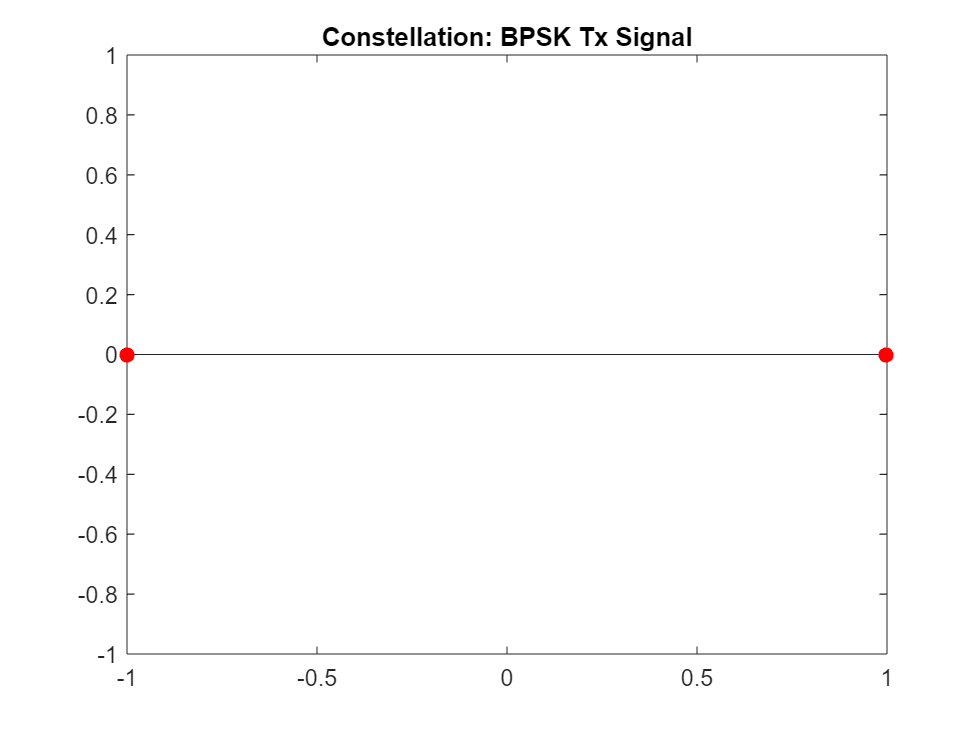

figure()
stem(sig_test,zeros(1,length(modulated)),'red','filled')
title("Constellation: BPSK Tx Signal")

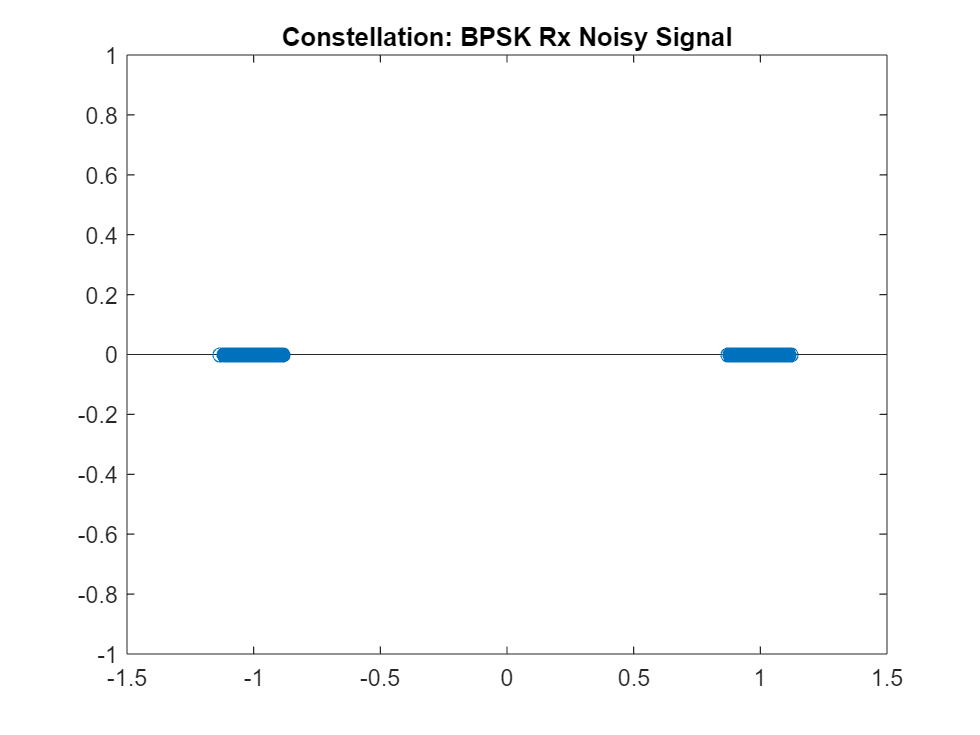

figure()
snr=30;
stem(awgn(sig_test,snr),zeros(1,length(modulated)))
title("Constellation: BPSK Rx Noisy Signal")

PSD

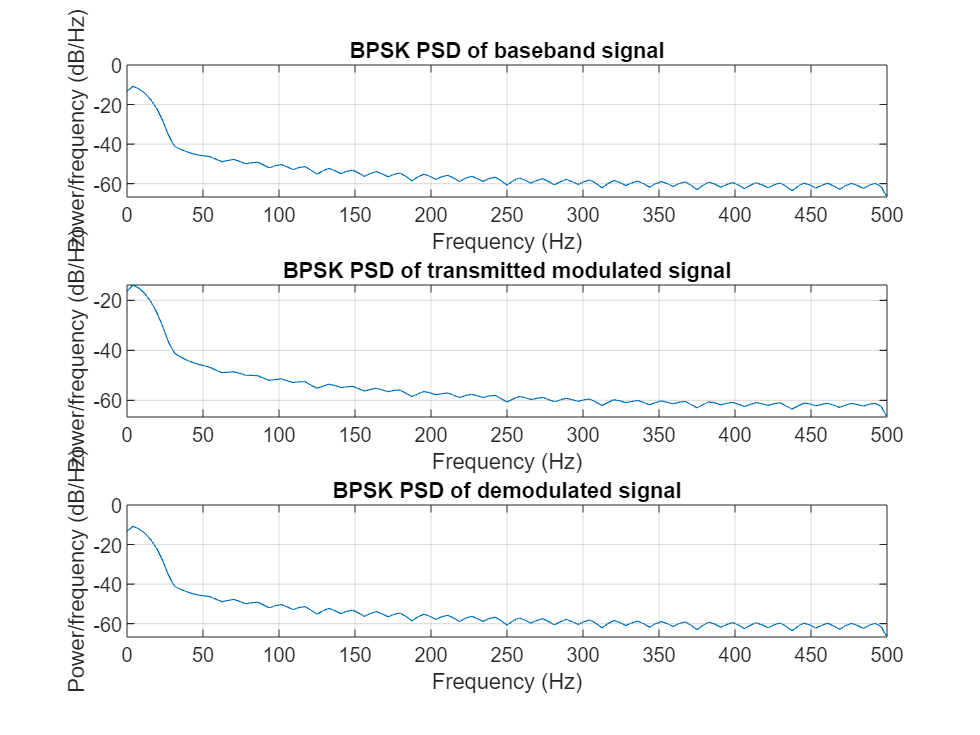

figure()
subplot(3,1,1)
h = spectrum.welch;
fs=1/dt;
Hpsd= psd(h,sig_test,'Fs',fs);
plot(Hpsd);
title('BPSK PSD of baseband signal')
subplot(3,1,2)
Hpsd= psd(h,modulated,'Fs',fs);
plot(Hpsd);
title('BPSK PSD of transmitted modulated signal')
subplot(3,1,3)
Hpsd= psd(h,sig_demod,'Fs',fs);
plot(Hpsd);
title('BPSK PSD of demodulated signal')


% h = spectrum.welch;
% fs=1/dt;
% Hpsd= psd(h,sig_test,'Fs',fs);
% plot(Hpsd);
% subplot(3,1,1)
% pwelch(sig_test,nooverlap)
% title('PSD of baseband signal')
% subplot(3,1,2)
% % pwelch(modulated,[],[],[],'psd')
% periodogram(sig_test)
% title('PSD of transmitted modulated signal')
% subplot(3,1,3)
% pwelch(sig_demod,[],[],[],'psd')
% title('PSD of demodulated signal')

BER

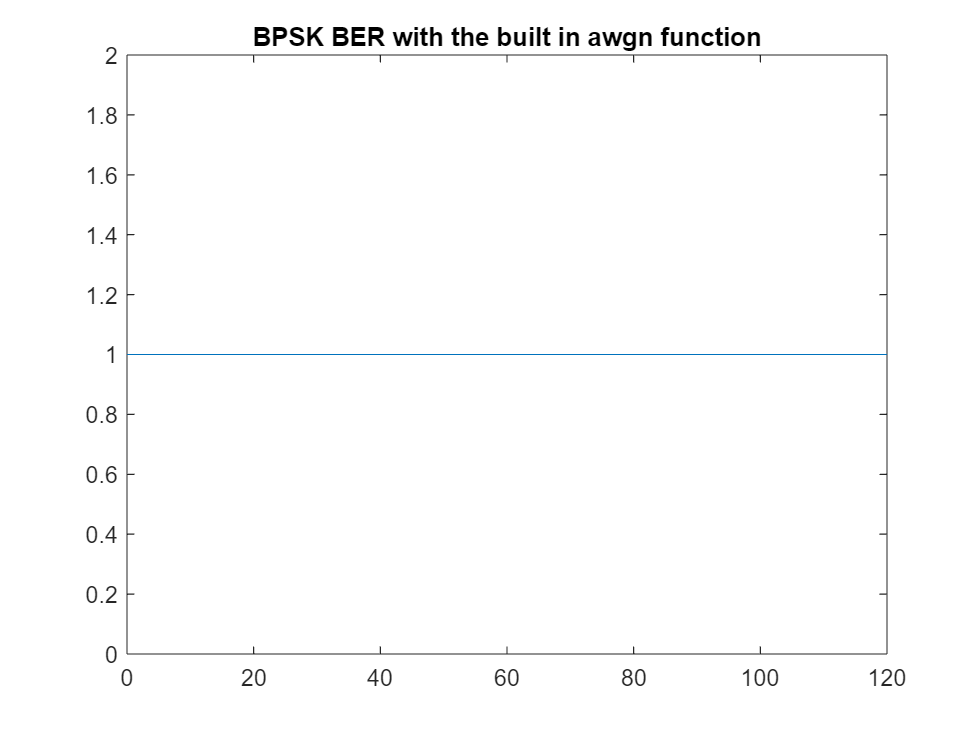

bers=[];
for i= 0:0.5:120
    snr=i;
    noisy_signal= awgn(modulated,snr);
    demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M);
    ber= calcBER(b,demodulated);
    bers=[bers ber];
end
figure()
plot([0: 0.5:120],bers)
title('BPSK BER with the built in awgn function')

Well, this built-in 'awgn()' gives 0 error even with significantly high noise values! 

Let's try some added random noise..

bers_bpsk=[]


bers_bpsk =

     []



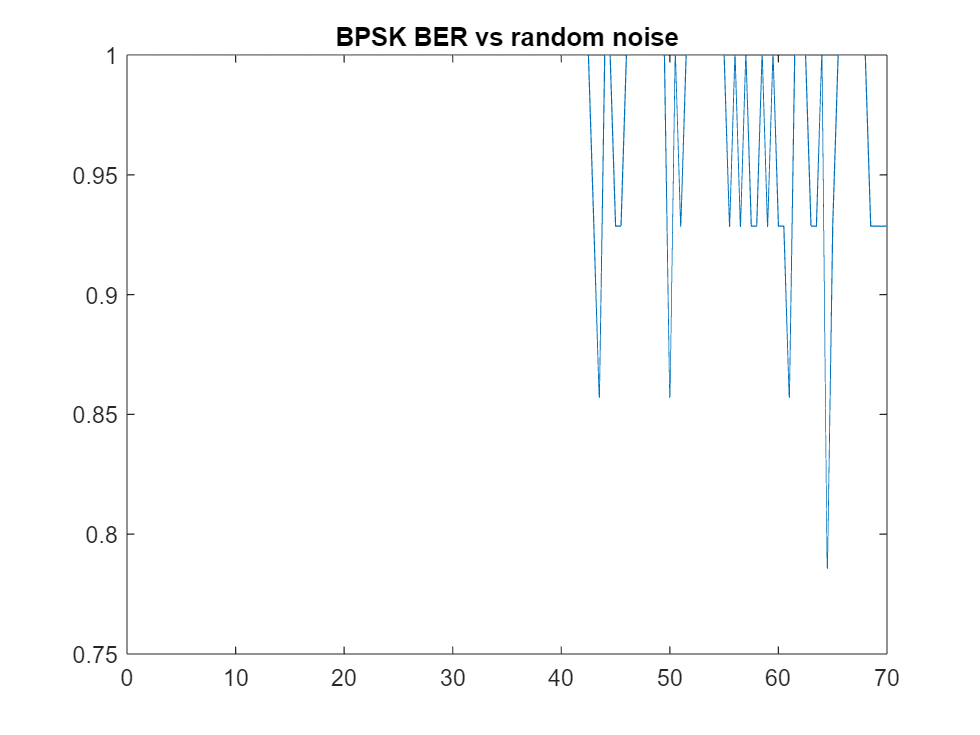

% r=rand(1,length(modulated));
difs=[];
figure()
for i= 0: 0.5:70
    
    noise= i*rand(1,length(modulated));
    noisy_signal= modulated+noise;
    demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M);
    ber= calcBER(b,demodulated);
    difs=[difs b-demodulated];
    bers_bpsk=[bers_bpsk ber];
end
figure()
plot([0: 0.5:70],bers_bpsk)
title('BPSK BER vs random noise')

# **QPSK**

% Modulation
M=4;
f1=1;
f2=10;
[modulated,y_i,y_q,in_phase_comps,quad_comps]= PSK_mod(b,Tb,dt,M);

i = 1

i = 3

i = 5

i = 7

i = 9

i = 11

i = 13

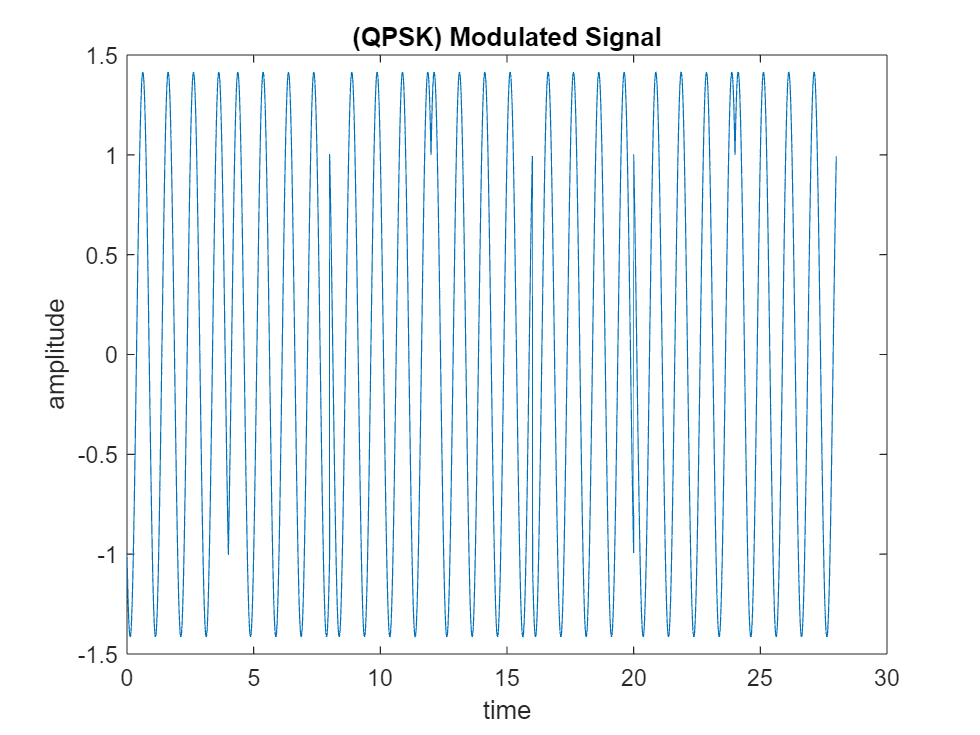

figure(2)
plot(tt,modulated);
title('(QPSK) Modulated Signal')
xlabel('time')
ylabel('amplitude')

figure(3)
    subplot(3,1,1)
    plot(tt,y_i)
    subplot(3,1,2)
    plot(tt,y_q)
    subplot(3,1,3)
    plot(tt,modulated);

Adding Noise to Signal

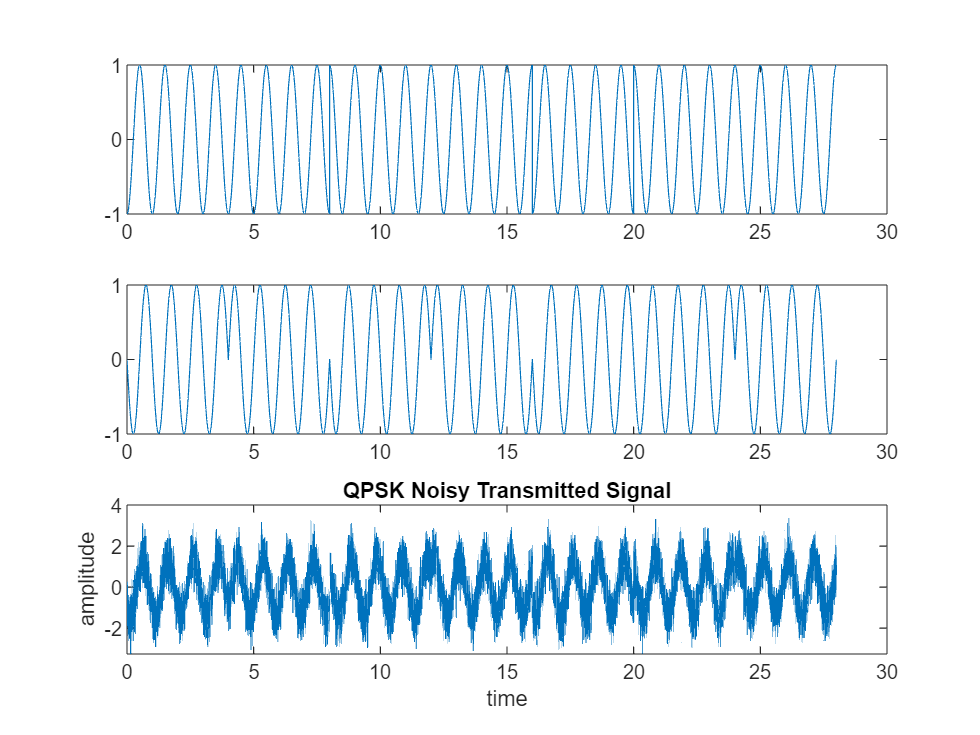

snr=5;
noisy_signal= awgn(modulated,snr);
figure(3)
plot(tt,noisy_signal)
title('QPSK Noisy Transmitted Signal')
xlabel('time')
ylabel('amplitude')

Demodulation

A=sqrt(2/Tb);
f=1;
demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M)

demodulated =      0     0     0     1     1     0     1     1     0     0     1     0     1     1


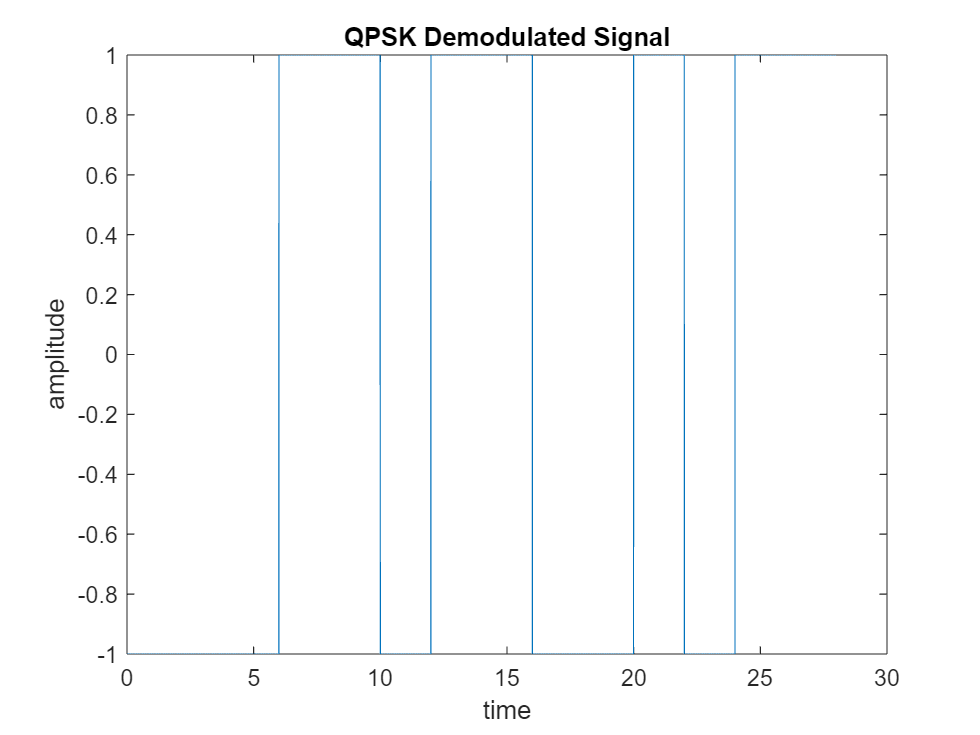

sig_demod= polarNRZ(demodulated,Tb,dt,L);
figure(4)
plot(tt,sig_demod)
title('QPSK Demodulated Signal')
xlabel('time')
ylabel('amplitude')

Add all to one plot for comarison

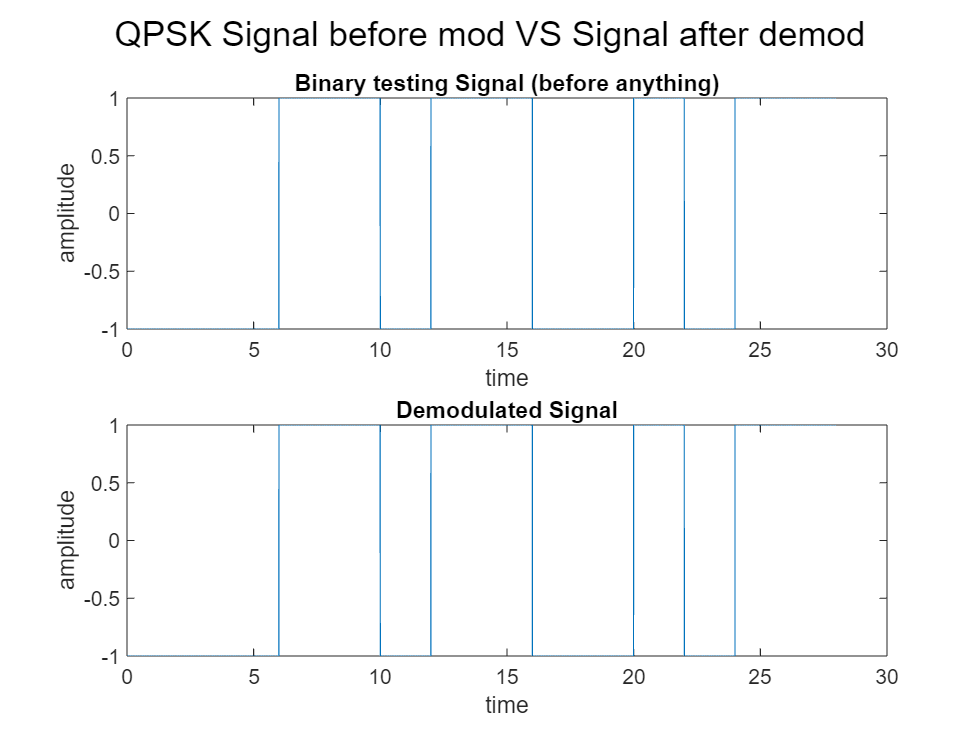

figure(5)
subplot(2,1,1)
plot(tt,sig_test)
title('Binary testing Signal (before anything)')
xlabel('time')
ylabel('amplitude')
subplot(2,1,2)
plot(tt,sig_demod)
title('Demodulated Signal')
xlabel('time')
ylabel('amplitude')

sgtitle('QPSK Signal before mod VS Signal after demod')

Constellation

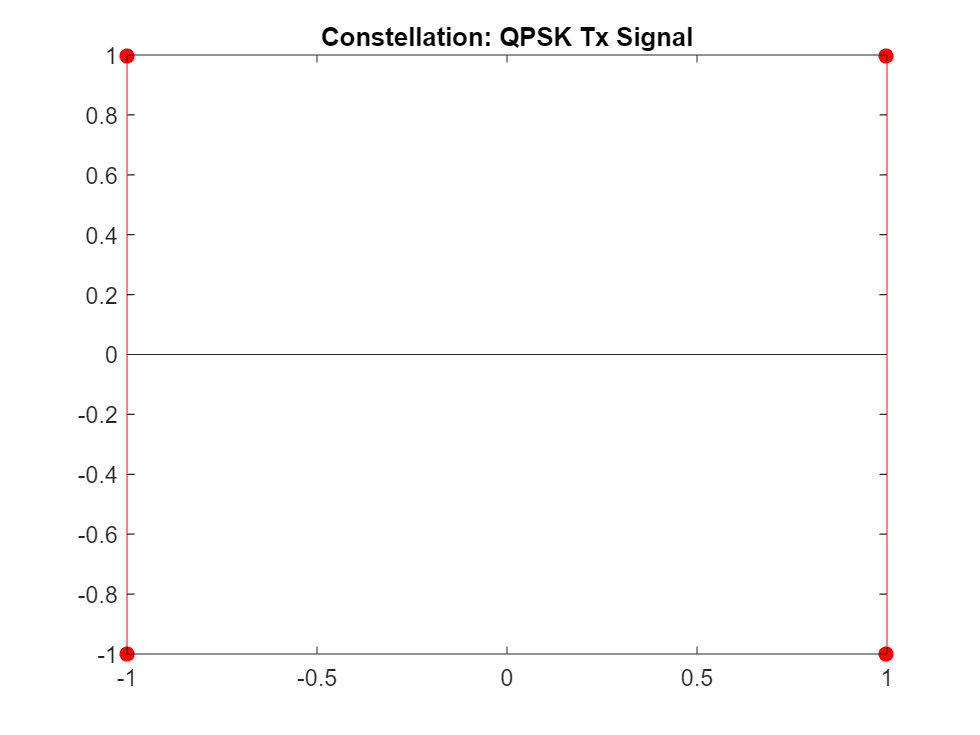


figure()
stem(in_phase_comps,quad_comps,'red','filled')
title("Constellation: QPSK Tx Signal")

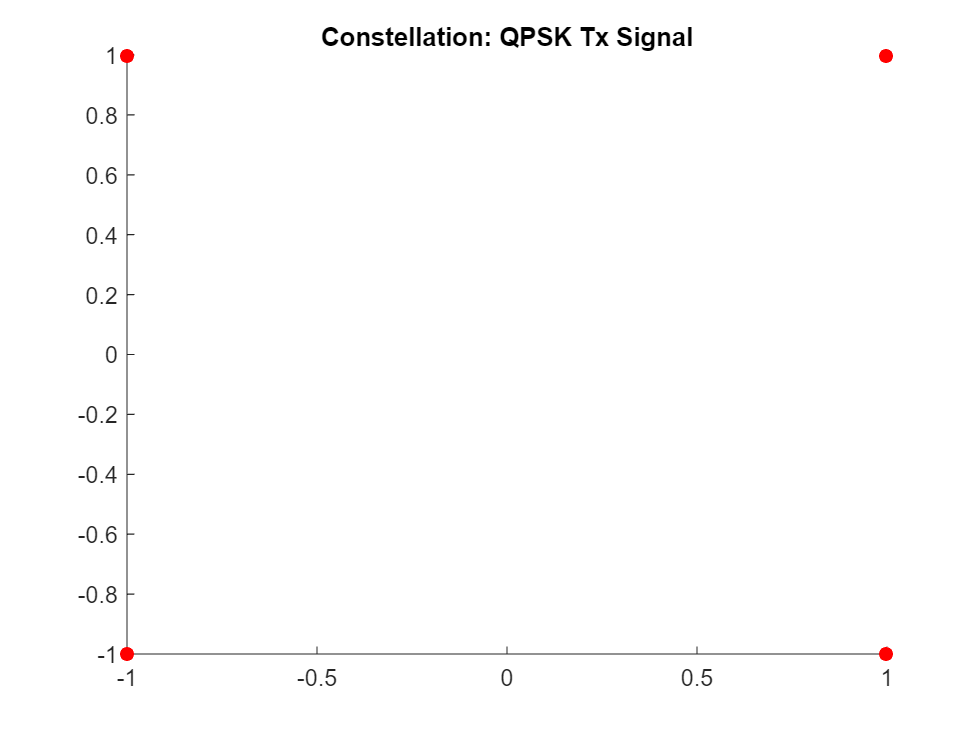

figure()
scatter(in_phase_comps,quad_comps,'red','filled')
title("Constellation: QPSK Tx Signal")

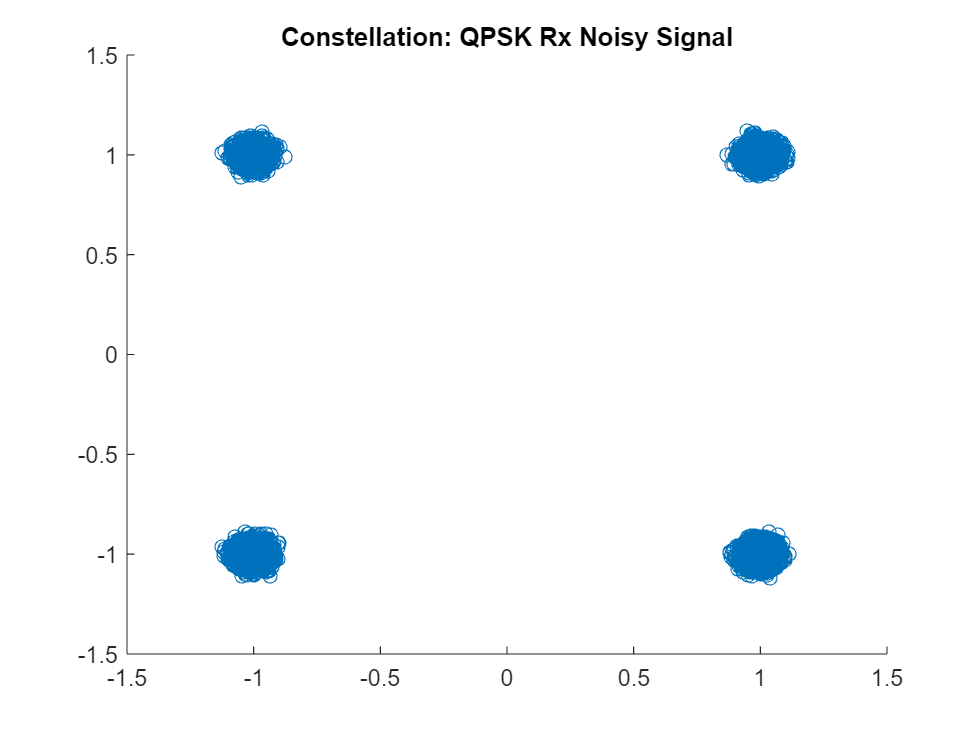

figure()
snr=30;
some_sig=polarNRZ(in_phase_comps,Tb,dt,length(in_phase_comps));
some_sig2=polarNRZ(quad_comps,Tb,dt,length(quad_comps));
scatter(awgn(some_sig,snr),awgn(some_sig2,snr))
title("Constellation: QPSK Rx Noisy Signal")

PSD

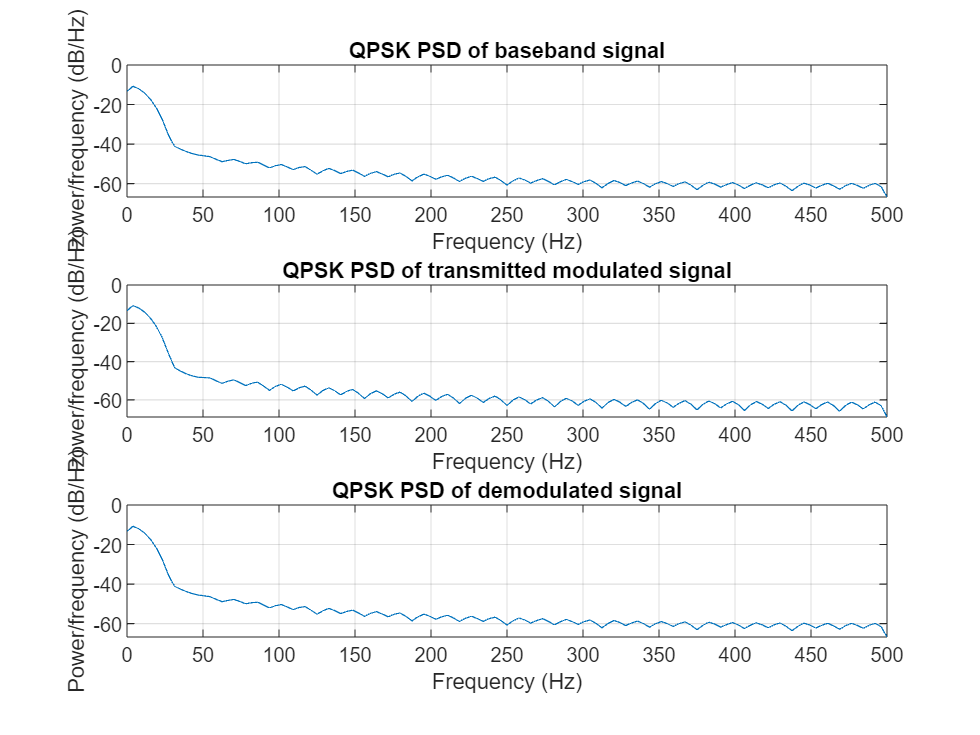

figure()
subplot(3,1,1)
h = spectrum.welch;
fs=1/dt;
Hpsd= psd(h,sig_test,'Fs',fs);
plot(Hpsd);
title('QPSK PSD of baseband signal')
subplot(3,1,2)
Hpsd= psd(h,modulated,'Fs',fs);
plot(Hpsd);
title('QPSK PSD of transmitted modulated signal')
subplot(3,1,3)
Hpsd= psd(h,sig_demod,'Fs',fs);
plot(Hpsd);
title('QPSK PSD of demodulated signal')


% h = spectrum.welch;
% fs=1/dt;
% Hpsd= psd(h,sig_test,'Fs',fs);
% plot(Hpsd);
% subplot(3,1,1)
% pwelch(sig_test,nooverlap)
% title('PSD of baseband signal')
% subplot(3,1,2)
% % pwelch(modulated,[],[],[],'psd')
% periodogram(sig_test)
% title('PSD of transmitted modulated signal')
% subplot(3,1,3)
% pwelch(sig_demod,[],[],[],'psd')
% title('PSD of demodulated signal')

BER

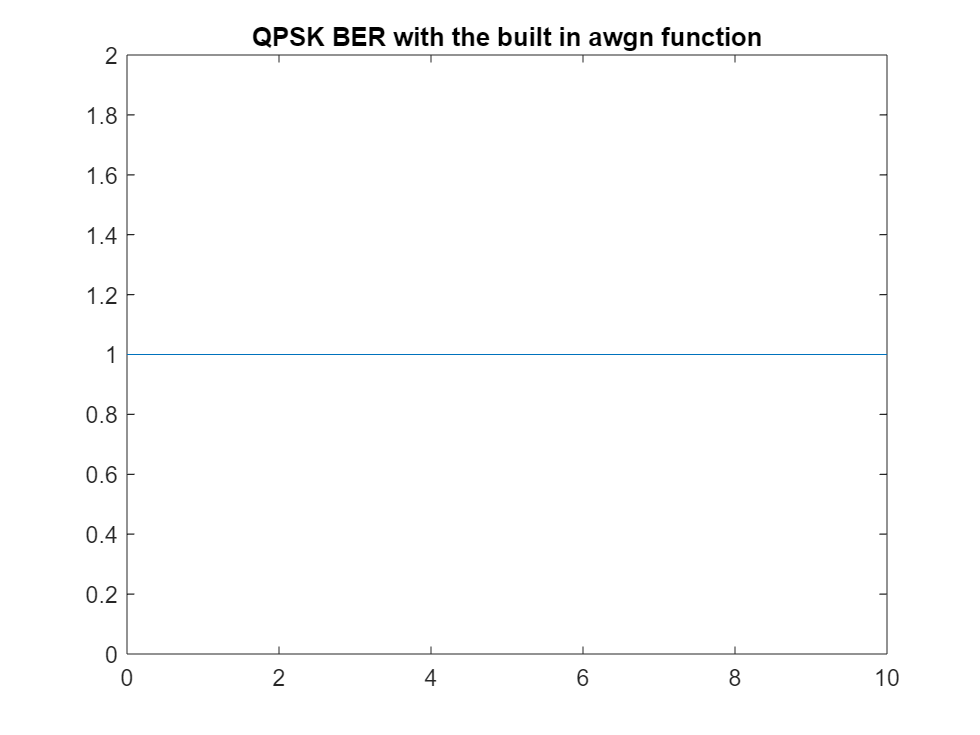

bers=[];
for i= 0: 0.001:10
    snr=i;
    noisy_signal= awgn(modulated,snr);
    demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M);
    ber= calcBER(b,demodulated);
    bers=[bers ber];
end
figure()
plot([0: 0.001:10],bers)
title('QPSK BER with the built in awgn function')

Well, this built-in 'awgn()' gives 0 error even with significantly high noise values! 

Let's try some added random noise..

bers_bpsk=[]


bers_bpsk =

     []



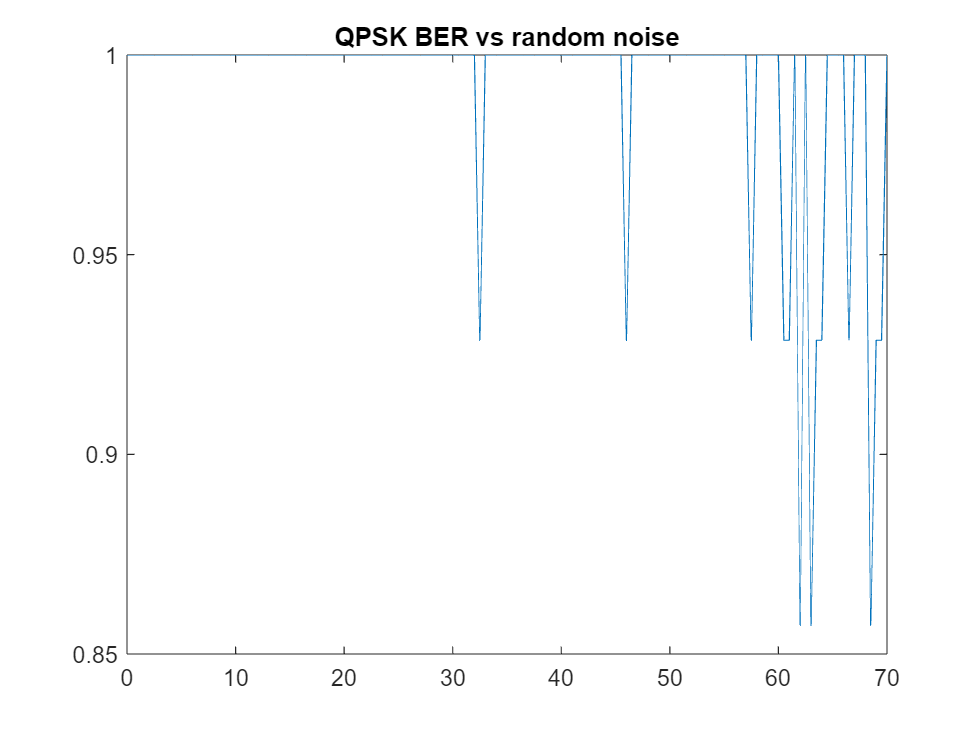

% r=rand(1,length(modulated));
difs=[];
figure()
for i= 0: 0.5:70
    
    noise= i*rand(1,length(modulated));
    noisy_signal= modulated+noise;
    demodulated= PSK_demod(noisy_signal,f,L,A,Tb,dt,M);
    ber= calcBER(b,demodulated);
    difs=[difs b-demodulated];
    bers_bpsk=[bers_bpsk ber];
end

figure()
plot([0: 0.5:70],bers_bpsk)
title('QPSK BER vs random noise')

## Functions Used

Function for Unipolar NRZ line-coding

function sig_pNRZ = polarNRZ(bitstream, Tb,dt,L)
    tb = 0:dt:Tb;
    tb(end)=[];
    zero_bit=-1*ones(1,length(tb));
    one_bit=ones(1,length(tb));
    sig_pNRZ=[];
    for i=1:L
        if(bitstream(i)==1)
            sig_pNRZ=[sig_pNRZ one_bit];
        else
            sig_pNRZ=[sig_pNRZ zero_bit];
        end
    end
    sig_pNRZ=[sig_pNRZ sig_pNRZ(end)];
end

Function for BER

function ber = calcBER(bits_tx, bits_rx)
    N=length(bits_tx);
%     diff=zeros(1,N);
%     for i=1:N
%         if(bits_tx(i)==bits_rx(i))
%             diff(i)=1;
%         end
%     end
    diff= sum(bits_rx==bits_tx);

    ber = diff/N;
end

Modulation Function

function [y_PSK,y_is,y_qs,in_phase_abs_vals,quad_abs_vals] = PSK_mod(bit_stream,Tb,dt,M)
%UNTITLED9 Summary of this function goes here
%   Detailed explanation goes here

L = length(bit_stream);
% Binary
tt= 0:dt:L*Tb;
tb = 0:dt:Tb;
tb(end)=[];
A = sqrt(2/Tb);
f=1;
carrier_cos = A*cos(2*pi*f*tb);
% carriers=[carrier_1 carrier_2];

% M=4;

% if M==2
    y_phases=zeros(1,L);
    
    ones_ind = find(bit_stream==1);
    zeros_ind = find(bit_stream==0);
    
    y_phases(ones_ind)=1;
    y_phases(zeros_ind)=-1;
    y_PSK=[];
    for i=1:L
        y_PSK= [y_PSK y_phases(i)*carrier_cos];
    end

    in_phase_abs_vals=y_phases(1:2:end);
    quad_abs_vals=y_phases(2:2:end);
if M==4 %QPSK
    y_PSK=[];
    y_is=[];
    y_qs=[];
    carrier_sin =A*sin(2*pi*f*tb);
    just_a_counter=0;
    for i=1:2:L
        y_i= y_phases(i) * carrier_cos;
        y_i= repmat(y_i,1,2);
        y_is=[y_is y_i];
        y_q= y_phases(i+1) * carrier_sin;
        y_q= repmat(y_q,1,2);
        y_qs=[y_qs y_q];
        y_PSK=[y_PSK y_i+y_q];

    end

    y_PSK= [y_PSK y_PSK(end)];
    
    y_is= [y_is y_is(end)];
    y_qs= [y_qs y_qs(end)];

else
    y_is=[];
    y_qs=[];
    y_PSK= [y_PSK y_PSK(end)];
    plot(tt,y_PSK);

end


end

Demodulation Function

function demod_stream = PSK_demod(x_recieved,f,N_syms,A,Tb,dt,M)
%UNTITLED3 Summary of this function goes here
%   Detailed explanation goes here
tb = 0:dt:Tb;
phi1 = A*cos(2*pi*f*tb);
phi2 = A*sin(2*pi*f*tb);
if(M==2)
    phi2=zeros(1,length(tb));
end

step = Tb/dt;
length(tb);

m=log2(M);
% demod_stream=zeros(1,N_syms);
demod_stream=[];
just_a_counter=0;
for i=1:step*m:length(x_recieved)
    if(just_a_counter>=N_syms/m)
        break;
    end
    just_a_counter=just_a_counter+1;
%     correlate 
    x1 = sum(x_recieved(i:i+step).*repmat(phi1,1,1));
    x2 = sum(x_recieved(i:i+step).*repmat(phi2,1,1));
% decide
    if(x1>0)
        demod_stream=[demod_stream 1];

    else 
        demod_stream=[demod_stream 0];
    end
    just_a_counter;
    if(M==4)            %QPSK
        if x2>0
            demod_stream=[demod_stream 1];
        else

            demod_stream=[demod_stream 0];
        end
    end
end




end